clearvars; close all; % clear variables in workspace and close all figures


% reading the data
data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');

% TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
% data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables % y = (x - min) / (max - min)

tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

% norm / denormalization function 
norm = @(x, Max, Min)((x-Min)/(Max-Min)); % y = (x - min) / (max - min)
denorm = @(y,Max,Min)(y*(Max-Min)+Min);
Min =mindp(1); Max= maxdp(1);

% clearvars -except data ndata mindp maxdp

% Training and Testing Data Split
TR = timerange('2018-01-01','2020-10-20 23:00:00', "closed");
trainvald = ndata(TR, :);   % training data

TR = timerange('2020-10-21','2021-10-20 23:00:00', "closed");
testd = ndata(TR, :);   % testing data 

## Training the Forecasters

### Inputs and Targets Creation

[inputs, blf_outputs, clf_outputs, testsetdt, p] = InputsCreation(ndata);


### Base Load Forecaster CNN training

numResponses=24;    % number of outputs
numFeatures=79;     % number of inputs

filterSize=[6 1];
numFilters=15;

% sets the training parameters
options = trainingOptions('adam', ...   
    'InitialLearnRate',0.001, ...
    'Verbose',false, ...
    'MaxEpochs',300,...     
    'Shuffle','every-epoch', ...    
    'Plots','none'); 

% Creating the layers of the network
layersCNN = ...
    [ imageInputLayer([numFeatures 1 1]) ...    % creates a 2d input
    , convolution2dLayer(filterSize,numFilters,'Padding','same') ...    % the convolution layer
    , reluLayer ...    % Rectified Linear Unit activation layer
    , maxPooling2dLayer([2 1]) ...
    , fullyConnectedLayer(numResponses) ...
    , regressionLayer] % creates a regression output layer

layersCNN =   1×6 Layer array with layers:

     1   ''   Image Input         79×1×1 images with 'zerocenter' normalization
     2   ''   Convolution         15 6×1 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                ReLU
     4   ''   Max Pooling         2×1 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected     24 fully connected layer
     6   ''   Regression Output   mean-squared-error


preshapedCnn=reshape(inputs(:),numFeatures,1,1,size(inputs,2)); % This is done to convert inputs to 4D so Conv2D can 
% accept it (NumFeatures     1     1   NumbOfDays)


outputsCnn = blf_outputs'; % before training the network the outputs should be NumdDays*NumbOfSamples

% Create training set
train_test_boundaryCnn = size(trainvald,1)/24; % gets the number of days in the training dataset

trainInd = 1:train_test_boundaryCnn; % index of train samples
trainXblf = preshapedCnn(:,:,:,trainInd);   % input of the training set
trainblfY = outputsCnn(trainInd,:);     % outputs of the training set 

testInd = train_test_boundaryCnn+1:size(preshapedCnn,4); % index of test samples
testXblf = preshapedCnn(:,:,:,testInd); % input of the testing set
testblfY = outputsCnn(testInd,:);       % outputs of the testing set

blfnet = trainNetwork(trainXblf,trainblfY,layersCNN,options); % trains the network

### Change in the Load Forecaster CNN Training

The structure of the BLF and CLF forecaster are the same. The only difference is in their outputs.

outputsCnn = clf_outputs'; % % before training the network the outputs should be NumdDays*NumbOfSamples

% Create training set
% train_test_boundaryCnn = size(trainvald,1)/24; %The entire year of 2019 is our test set

% trainInd = 1:train_test_boundaryCnn; % index of train samples
trainXclf = preshapedCnn(:,:,:,trainInd);   % input and outputs of the training set
trainclfY = outputsCnn(trainInd,:);% before

testInd = train_test_boundaryCnn+1:size(preshapedCnn,4); % index of test samples
testXclf = preshapedCnn(:,:,:,testInd); % input of the testing set
testclfY = outputsCnn(testInd,:);   % outputs of the testing set


clfnet = trainNetwork(trainXclf,trainclfY,layersCNN,options); % trains the clf network

## Predict the test dataset

% Generate BLF forecasts
raw_blf = predict(blfnet,testXblf);   % making predictions using the inputs of the test set
yBLF = denorm(raw_blf, Max,Min);   % denormalization of the output

raw_actuals = testblfY; 
actuals = denorm(raw_actuals, Max,Min); % the actual values

yBLF = yBLF';
actuals = actuals';

% Generate CLF forecasts
prevday = buffer(testd.DemandMW,24);   % gets the demand of the previous days
raw_clf = predict(clfnet,testXclf)' + prevday(:,1:end-1); 
yCLF = denorm(raw_clf, Max,Min); 

% Generate RLS forecasts
days = size(yBLF);
days = days(2);

% calls the rls combiner function
[yRLS, w] = RLS_Combiner(raw_blf', raw_clf, raw_actuals', days); % uses the normalized values as inputs
yRLS = denorm(yRLS, Max,Min); 


% dates
dtCnn= buffer(datenum(ndata.DateTime),24);  
traindtCnn=(dtCnn(:,trainInd));     
testdtCnn=(dtCnn(:,testInd));

trainvaldt = datetime(datevec(traindtCnn(:))); % the datetime of the training set
testsetdt = datetime(datevec(testdtCnn(:))) + hours(24); % the datetime of the test set

### Calculate errors

[Metrics,eBLF, blf_AEs, blf_APEs, eCLF, clf_AEs, clf_APEs,...
eRLS, rls_AEs, rls_APEs, blf_MAPE, clf_MAPE, rls_MAPE] = ErrorMetrics(actuals, yBLF, yCLF, yRLS);

Metrics

Metrics = 6×4 table
                   Metrics                      BLF        CLF         RLS   
    ______________________________________    _______    ________    ________

    {'MAPE - Mean Absolute Percent Error'}     4.0014      3.9014      3.8708
    {'ME - Mean Error'                   }    -1.1941    -0.83315    -0.13592
    {'MAE - Mean Absolute Error'         }     4.8333       4.702      4.6982
    {'MSE - Mean Squared Error'          }     65.864      62.692      64.867
    {'RMSE - Root Mean Squared Error'    }     8.1157      7.9178       8.054
    {'Standard Deviation'                }     8.0278      7.8743      8.0533


### Plots of the Test dataset

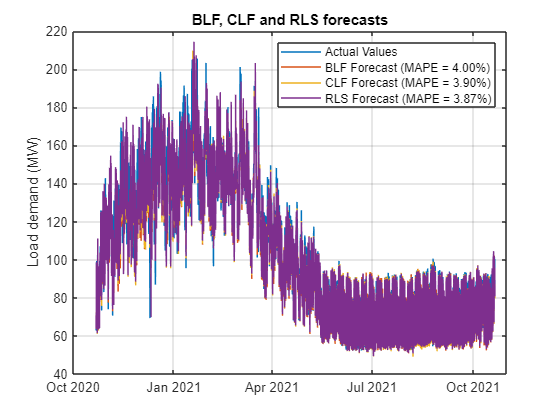

figure;

% plot actual values
plot(testsetdt, actuals(:), 'DisplayName','Actual Values')
title('BLF, CLF and RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot blf forecast
DisplayName = num2str(blf_MAPE, 'BLF Forecast (MAPE = %.2f%%)');
plot(testsetdt,yBLF(:), 'DisplayName', DisplayName)

% plot clf forecast
DisplayName = num2str(clf_MAPE, 'CLF Forecast (MAPE = %.2f%%)');
plot(testsetdt,yCLF(:), 'DisplayName', DisplayName)

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(testsetdt,yRLS(:), 'DisplayName', DisplayName)
legend('show')

## Peak Detection

[DailyPeak]= PeakDetection(testsetdt, actuals, yRLS);
DailyPeak

DailyPeak = 364×7 timetable
       Time        ActPkHr    ActPk     PredPkHr    PredPk    TimeDiff    ValueDiff     APEs  
    ___________    _______    ______    ________    ______    ________    _________    _______

    22-Oct-2020      14       99.352        9         99         -5       -0.35206     0.35436
    23-Oct-2020      12        102.8       14        111          2         8.2017      7.9784
    24-Oct-2020      10       93.475       14         96          4         2.5252      2.7014
    25-Oct-2020      19       107.11       14        104         -5        -3.1055      2.8994
    26-Oct-2020       9       125.86        

% Overall MAPE
DayPk_MAPE = mean(DailyPeak.APEs)

DayPk_MAPE = single
3.6592

% gives you the hours, minutes, seconds
DayPk_TimeDiff_MBE = round(minutes(hours(mean(DailyPeak.TimeDiff)))) 

DayPk_TimeDiff_MBE = 3

DayPk_TimeDiff_MAE = round(minutes(hours(mean(abs(DailyPeak.TimeDiff)))))

DayPk_TimeDiff_MAE = 164

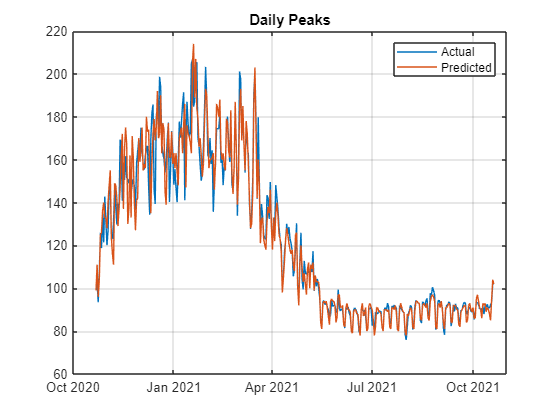


% Plots of the daily peaks
figure;
plot(DailyPeak.Time, DailyPeak.ActPk, 'DisplayName','Actual')
title('Daily Peaks')
hold on
plot(DailyPeak.Time, DailyPeak.PredPk, 'DisplayName', 'Predicted')
grid on
legend('show')